%写一个具体的流程图给老师

% 窗长和频率相关
% rigsure加平滑
% 2% control chart
% bayes threshold

clc; clear;
warning off;

fs=500;%采样频率


% % load all files in selected folder
ftype='.txt';
pname='/Users/yskj/Desktop/项目/LFPDecoding/fixed_data/';

txtfile = [pname,'*',ftype];
file  = dir(txtfile);
nside = size(file,1);
Mean  = zeros(1, nside);
Var   = zeros(1, nside);
ERROR = zeros(1, nside);
SynRatio= zeros(1, nside);
 
for iside=1:nside%21
%iside = 1;

fname=file(iside).name
impfilename=[pname,fname];
sori=importdata(impfilename,'\t',1);

%{
load("LFP_delete15.mat");
sPAG=LFP_delete15(:,1);
fsResample = 256;
sPAGResample=resample(sPAG,fsResample,fs);

signal = sPAGResample;
%}

%2-4:  fsresample = 256;node=[6 6];centralFreq = 3;
%4-8:  fsresample = 256;node=[6 5];centralFreq = 6;
%8-16: fsresample = 256;node=[6 4];centralFreq = 12;
%16-32:fsresample = 256;node=[6 3];


%2.5-5:  
fsResample = 320;node=[6 6];centralFreq = 4;
%5-10:   fsResample = 320;node=[6 5];centralFreq = 7;
%10-20:  fsResample = 320;node=[6 4];centralFreq = 15;
%20-40:  fsResample = 320;node=[6 3];centralFreq = 30;

%40-80:  fsResample = 320;node=[6 2];centralFreq = 60;

%6-12 :fsresample = 384;node=[5 5];centralFreq = 12;
%12-24:fsresample = 384;node=[5 4];

sgpi=sori.data(:,2);
sgpiResample=resample(sgpi,fsResample,fs);
signal = sgpiResample(fsResample*5:fsResample*10*60);



[states, tVector] = NeuralSynSWT(signal, fsResample, node, centralFreq, '20-40');

%{
figure;
h1 = histogram(states);
title(['Syncronization Metric Histogram window = ',num2str(1/centralFreq * 60),'s']);
%[c,lags] = xcorr(states);
%stem(lags,c)
%}

%{

Number = length(states);
windowNum = round(1/centralFreq * fsResample * 4);
step = round(0.02 * fsResample);
i = 1;
while(step*i+windowNum<Number)
    CurrentSignal = states(1+step*(i-1):step*(i-1)+windowNum);
    SignalSeg(i,:) = CurrentSignal;
    XHmm(i,:) = tVector(1+step*(i-1):step*(i-1)+windowNum);
    i = i+1;
end

[r,c]=size(SignalSeg); 
DataHmmCell = mat2cell(SignalSeg,r,c);

state_num = 3;
%p = 25;  % feature dim
[p_start, Prob, phi, loglik] = ChmmGauss(DataHmmCell, state_num);

% Calculate p(X) & vertibi decode
logp_xn_given_zn = Gauss_logp_xn_given_zn(DataHmmCell{1}, phi);
[~,~, loglik] = LogForwardBackward(logp_xn_given_zn, p_start, Prob);
path = LogViterbiDecode(logp_xn_given_zn, p_start, Prob);

color = ['k','r','b'];

figure;
SignalSeg = SignalSeg(1:400,:);
XHmm = XHmm(1:400,:);

[r,c]=size(SignalSeg);
for i = 1:r
    if mod(i,3)==2
        plot(XHmm(i,:),SignalSeg(i,:),'Color',color(path(i)));hold on;
    end
end
xlabel('Time/s');
ylabel('Synchronization States');
title('HMM States in 20-40hz');


figure;
xvalues = {'Black','Red','Blue'};
yvalues = {'Black','Red','Blue'};
cdata = reshape(Prob,3,3);
h = heatmap(xvalues,yvalues,cdata);
h.Title = 'Transition Probility';
h.XLabel = 'States';
h.YLabel = 'States';
%}

Mean(iside) = mean(states);
Var (iside) = var(states);
[A3, sgm5]  = ARLSS(states,5);
ERROR(iside) = sgm5;

SynRatio(iside) = length(find(states>mean(states)))/length(states);

end

fname = '20170423wjz_L_rest_shp1_500hza12.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20170423wjz_R_rest_shp1_500hza12.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20170719ycf_L_restan-sit_shp1a12.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20170719ycf_R_restan-sit_chodr3412_shp1a12.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20170918zxl_L_restan-sit_shp1a12.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20170918zxl_R_restan-sit_shp1a12.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171204_cf_L_restan-sits_shp1a100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171204_cf_R_restan-sits_shp1a100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171205wyh_L_restan-sits_shp1a100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171205wyh_R_restan-sits_shp1pfa100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171218rgx_L_restan-sits_shp1pfa100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171218rgx_R_restan-sits_shp1a100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20171225llm_R_restan-sits_shp1a100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20180131slq_L_restan-sit_hp100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = '20180131slq_R_restan-sit_hp100.txt'


   Neural State
  |-                                              -|
  ************************************************

fname = 'sn20171225llm_L_restan-sits_shp1a100.txt'


   Neural State
  |-                                              -|
  ************************************************


BFMDRS = [16 16 11 11 27 27 12 12 29 29 24 24 36 18 18 36];%10min
Test = [BFMDRS',Mean',Var', ERROR', SynRatio'];
[R,P]=corr(Test);

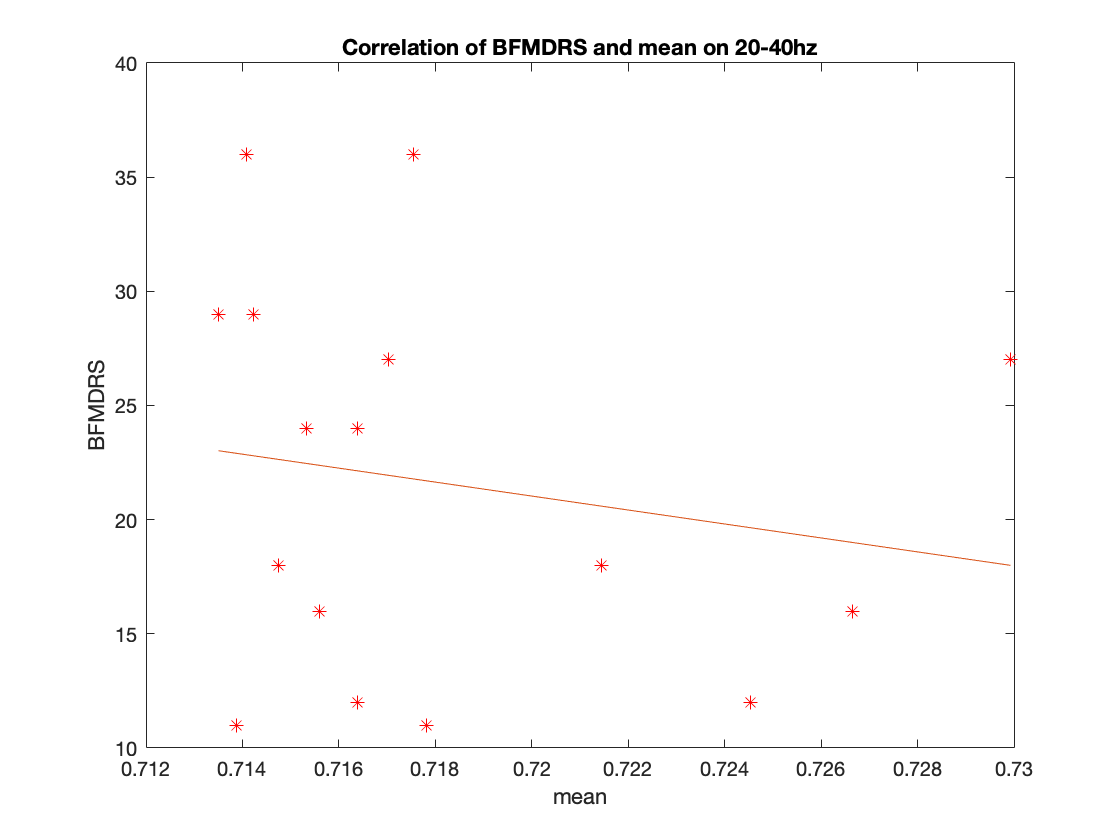

figure;
x = Mean';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('mean'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and mean on 20-40hz'); % 图形标题
hold off;

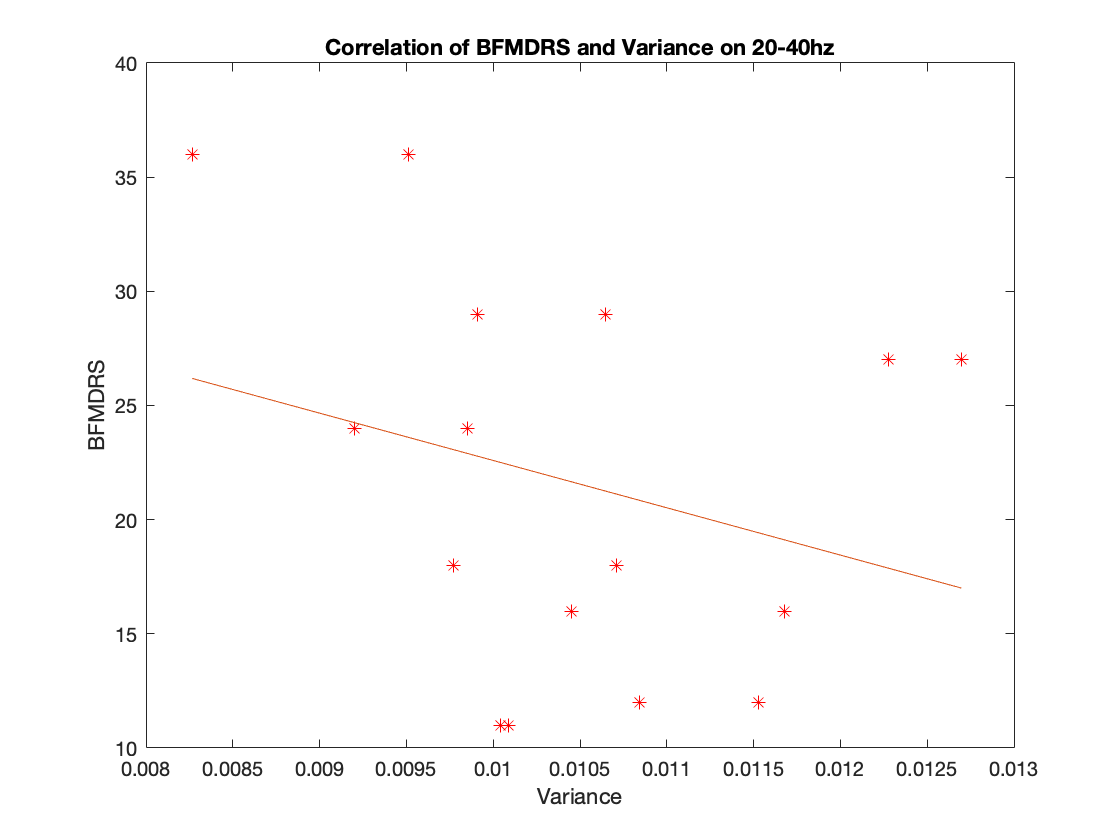


figure;
x = Var';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('Variance'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title(['Correlation of BFMDRS and Variance on 20-40hz']); % 图形标题
hold off;

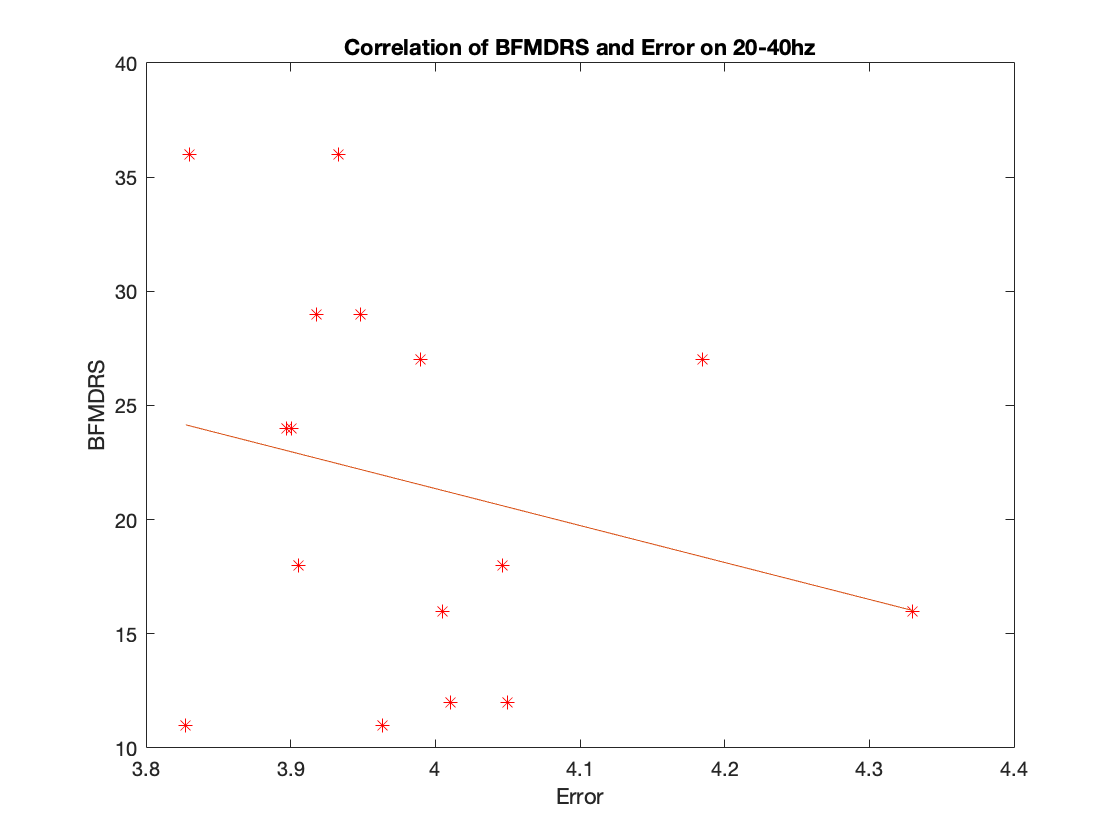



figure;
x = ERROR';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('Error'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and Error on 20-40hz'); % 图形标题
hold off;

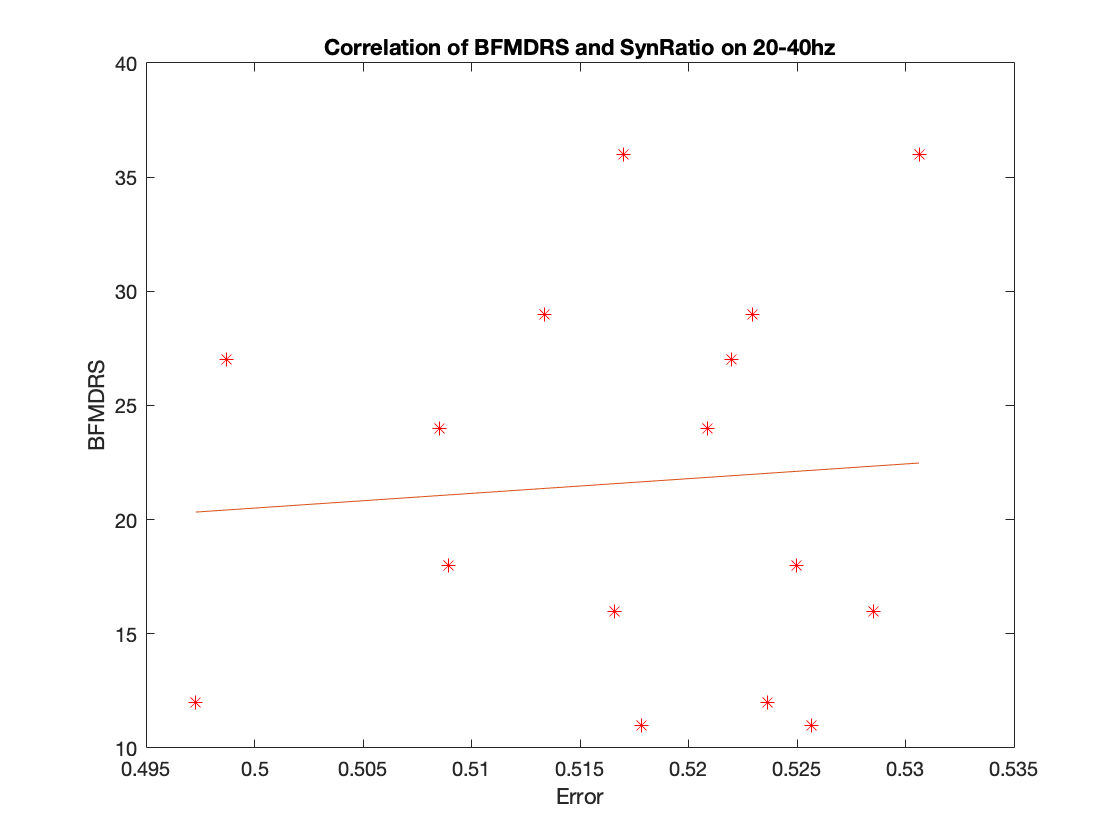



figure;
x = SynRatio';
y = BFMDRS';
plot(x,y,'r*');
hold on
%{
%回归分析
[b,bint,r,rint,stats]=regress(y,x);
%预测及作回归线图
z=b*x;
plot(x,z,'-');
xlabel('rate1'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and 4-8hz rate0'); % 图形标题
hold off;
%}

%回归分析
%[b,bint,r,rint,stats]=regress(y,x);
p = polyfit(x,y,1);
%预测及作回归线图
x = sort(x);
xi = linspace(min(x),max(x),30);
z = polyval(p,xi);
plot(xi,z,'-');
xlabel('Error'); % x轴注解
ylabel('BFMDRS'); % y轴注解
title('Correlation of BFMDRS and SynRatio on 20-40hz'); % 图形标题
hold off;